%% main_LQR_cart_pendulum.m
clc; clear; close all;

%% Physical parameters (change if you want)
m = 0.2;      % pendulum mass      [kg]
M = 1.0;      % cart mass          [kg]
L = 0.5;      % CoG-to-pivot       [m]
J = 0.006;    % inertia about CoG  [kg m^2]
k = 0.05;     % cart viscous friction  [N s/m]
g = 9.81;     % gravity            [m/s^2]

params = [m M L J k g];

%% ---- Linearized model around (theta=0, theta_dot=0, y=0, y_dot=0, F=0)

a1 = J + m*L^2;
a2 = M + m;
b  = m*L;
Delta = a1*a2 - b^2;        % determinant in linearization

% State: x = [theta; theta_dot; y; y_dot]
A = zeros(4,4);
A(1,2) = 1;                                  % theta_dot
A(2,1) = (a2*b*g)/Delta;                     % theta term in theta_ddot
A(2,4) = (b*k)/Delta;                        % y_dot term in theta_ddot
A(3,4) = 1;                                  % y_dot
A(4,1) = -(b^2*g)/Delta;                     % theta term in y_ddot
A(4,4) = -(a1*k)/Delta;                      % y_dot term in y_ddot

B = [0;
     -b/Delta;
      0;
      a1/Delta];

disp('A matrix (linearized):'); disp(A);

A matrix (linearized):
         0    1.0000         0         0
   20.5804         0         0    0.0874
         0         0         0    1.0000
   -1.7150         0         0   -0.0490



disp('B matrix (linearized):'); disp(B);

B matrix (linearized):
         0
   -1.7483
         0
    0.9790




%% ---- LQR design (full-state feedback: F = -K x)

Q = diag([200, 20, 20, 5]);   % state penalties [theta, theta_dot, y, y_dot]
R = 0.5;                       % input penalty

K = lqr(A,B,Q,R);
disp('LQR gain K:'); disp(K);

LQR gain K:
  -64.6567  -15.5845   -6.3246   -8.8927




eig_cl = eig(A - B*K);
disp('Closed-loop eigenvalues (linearized):'); disp(eig_cl);

Closed-loop eigenvalues (linearized):
 -12.6722 + 0.0000i
  -3.2550 + 0.0000i
  -1.3306 + 0.9269i
  -1.3306 - 0.9269i



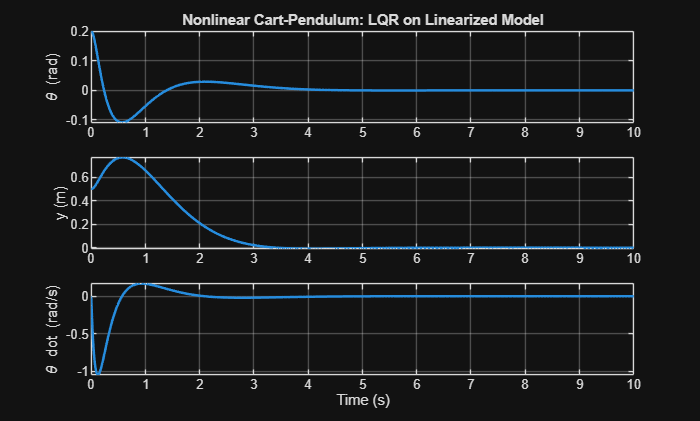


%% ---- Simulate closed-loop NONLINEAR system with LQR

% Initial condition: [theta; theta_dot; y; y_dot]
x0 = [0.2; 0.0; 0.5; 0.0];     % small angle + cart offset

tspan = [0 10];
[t, x] = ode45(@(t,x) cart_pendulum_nonlinear_LQR(t,x,params,K), tspan, x0);

theta   = x(:,1);
dtheta  = x(:,2);
y_pos   = x(:,3);
dy      = x(:,4);

%% ---- Plots
figure;
subplot(3,1,1);
plot(t, theta, 'LineWidth', 1.5); grid on;
ylabel('\theta (rad)');
title('Nonlinear Cart-Pendulum: LQR on Linearized Model');

subplot(3,1,2);
plot(t, y_pos, 'LineWidth', 1.5); grid on;
ylabel('y (m)');

subplot(3,1,3);
plot(t, dtheta, 'LineWidth', 1.5); grid on;
ylabel('\theta dot (rad/s)');
xlabel('Time (s)');


function dx = cart_pendulum_nonlinear_LQR(t, x, params, K)
% Nonlinear dynamics of inverted pendulum on a cart
% State x = [theta; theta_dot; y; y_dot]
% Control: F = -K * x (full-state feedback from LQR)

    theta  = x(1);
    dtheta = x(2);
    y      = x(3); %#ok<NASGU>   % not used explicitly in dynamics
    dy     = x(4);

    % Unpack parameters
    m = params(1);
    M = params(2);
    L = params(3);
    J = params(4);
    k = params(5);
    g = params(6);

    % Full-state feedback (about zero equilibrium)
    F = -K * x;    % scalar

    % Short-hand
    a1 = J + m*L^2;
    a2 = M + m;
    b  = m*L;
    c  = cos(theta);
    s  = sin(theta);

    % Inertia matrix and RHS from original equations:
    % a1*theta_dd + b*c*y_dd = b*g*s
    % b*c*theta_dd + a2*y_dd = F + b*dtheta^2*s - k*dy

    Mq  = [a1,    b*c;
           b*c,   a2];

    rhs = [b*g*s;
           F + b*dtheta^2*s - k*dy];

    dd  = Mq \ rhs;      % [theta_dd; y_dd]
    ddtheta = dd(1);
    ddy     = dd(2);

    % Assemble state derivative
    dx      = zeros(4,1);
    dx(1)   = dtheta;
    dx(2)   = ddtheta;
    dx(3)   = dy;
    dx(4)   = ddy;
end
